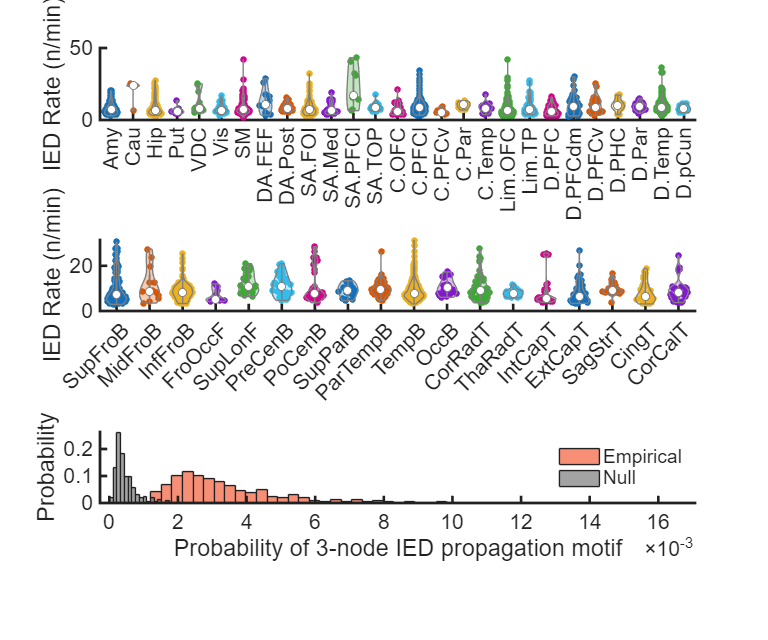

% Electrode contacts number and IED rate distribution
clc;clear;close all; addpath z_toolbox\Violinplot;
subG = {'sub-0001', 'sub-0002', 'sub-0003', 'sub-0004', 'sub-0005', ...
        'sub-0007', 'sub-0008', 'sub-0009', 'sub-0010', 'sub-0011', ...
        'sub-0012', 'sub-0013', 'sub-0014', 'sub-0015', 'sub-0016', ...
        'sub-0017', 'sub-0019', 'sub-0020', 'sub-0021', 'sub-0022', ...
        'sub-0023', 'sub-0028', 'sub-0029', 'sub-0031', 'sub-0033', ...
        'sub-0034', 'sub-0035', 'sub-0036', 'sub-0039', 'sub-0046', ...
        'sub-0047', 'sub-0050', 'sub-0052', 'sub-0054', 'sub-0062', ...
        'sub-0063', 'sub-0066', 'sub-0067', 'sub-0074', 'sub-0077', ...
        'sub-0087', 'sub-0089', 'sub-0092', 'sub-0093', 'sub-0094', ...
        'sub-0113', 'sub-0115'};
ASEGlabels = {'Acc', 'Amy', 'Cau', 'Hip', 'Pal', 'Put', 'Tha', 'VDC'};
Yeo7labels = {'Vis', 'SM', 'DA.FEF', 'DA.Post', ...
                'SA.FOI', 'SA.Med', 'SA.PFCl', 'SA.PFCv', 'SA.PO', ...
                'SA.PrC', 'SA.TOP', ...
                'C.Cing', 'C.OFC', 'C.PFCl', 'C.PFCmp', 'C.PFCv', ...
                'C.Par', 'C.Temp', 'C.pCun', ...
                'Lim.OFC', 'Lim.TP', ...
                'D.PFC', 'D.PFCdm', 'D.PFCv', 'D.PHC', 'D.Par', ...
                'D.Temp', 'D.pCun'};
JHUlabels = {'SupFroB', 'MidFroB', 'InfFroB', 'FroOccF', ...
            'SupLonF', 'PreCenB' 'PoCenB', 'SupParB', ...
            'ParTempB', 'TempB', 'OccB', 'CorRadT', 'ThaRadT', ...
            'IntCapT', 'ExtCapT', 'SagStrT', 'CingT', ...
            'CorCalT', 'UncF'};
elecPath = 'step1_AwakeSEEG_BPfiltering_Age16Up';
IEDpath = 'step3_IEDs';
Yeo7IEDrate = cell(length(Yeo7labels), 1);
ASEGIEDrate = cell(length(ASEGlabels), 1);
JHUIEDrate = cell(length(JHUlabels), 1);
for nS = 1:length(subG)
    subID = subG{nS};
    % Load IED data
    load(fullfile(IEDpath, [subID, '_task-awake_ref-TCA_IEDs-diffTD.mat']));
    IEDlabel = IEDs{1}{1}.label; % channel label
    % Calculate IED rate (n/min)
    IEDcountSum = zeros(length(IEDlabel), 1);
    for nRun = 1:length(IEDs)
        IEDchanPartici = IEDs{nRun}{6}.IEDchanPartici{1};
        IEDcountSum = IEDcountSum+sum(IEDchanPartici, 2);
    end
    IEDrate = IEDcountSum./(nRun*5);
    % Map channel to atlas
    load(fullfile(elecPath, subID, [subID, '_ROI-3mm_contactAnatomy.mat']));
    chanAtlasLabel = {};
    for nChan = 1:size(IEDlabel, 1)
        a = strcmp(IEDlabel{nChan}, contAnat.label);
        b = strcmp(contAnat.Yeo7_51(a==1), Yeo7labels);
        if any(b)
            Yeo7IEDrate{b==1} = [Yeo7IEDrate{b==1}, IEDrate(nChan)];
        end
        c = strcmp(contAnat.ASEG(a==1), ASEGlabels);
        if any(c)
            ASEGIEDrate{c==1} = [ASEGIEDrate{c==1}, IEDrate(nChan)];
        end
        d = strcmp(contAnat.JHU(a==1), JHUlabels);
        if any(d)
            JHUIEDrate{d==1} = [JHUIEDrate{d==1}, IEDrate(nChan)];
        end
    end
end
% Prepare data for YEO-7 violinplot visualization
Yeo7IEDrate = [ASEGIEDrate; Yeo7IEDrate];
Yeo7labels = [ASEGlabels, Yeo7labels];
chanCount = [];
for n = 1:length(Yeo7IEDrate)
    chanCount(n) = length(Yeo7IEDrate{n});
end
idx = find(chanCount>=5);
Yeo7IEDrate = Yeo7IEDrate(idx);
Yeo7labels = Yeo7labels(idx);
N = 0; Yeo7IEDrateList = []; Yeo7atlasList = {};
for nA = 1:length(Yeo7IEDrate)
    for m = 1:length(Yeo7IEDrate{nA})
        N = N +1;
        Yeo7IEDrateList(N) = Yeo7IEDrate{nA}(m);
        Yeo7atlasList{N} = Yeo7labels{nA};
    end
end
% Prepare data for JHU violinplot visualization
chanCount = [];
for n = 1:length(JHUIEDrate)
    chanCount(n) = length(JHUIEDrate{n});
end
idx = find(chanCount>=5);
JHUIEDrate = JHUIEDrate(idx);
JHUlabels = JHUlabels(idx);
N = 0; JHUIEDrateList = []; JHUatlasList = {};
for nA = 1:length(JHUIEDrate)
    for m = 1:length(JHUIEDrate{nA})
        N = N +1;
        JHUIEDrateList(N) = JHUIEDrate{nA}(m);
        JHUatlasList{N} = JHUlabels{nA};
    end
end
% IED rate distribution across brain regions
figure('Units', 'centimeters', 'Position', [5, 5, 36, 30]);
subplot(3, 1, 1);
vs2 = violinplot(Yeo7IEDrateList, Yeo7atlasList, 'GroupOrder', Yeo7labels);
xlim([0.5, length(Yeo7labels)+0.5]);
ylabel('IED Rate (n/min)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
subplot(3, 1, 2);
vs2 = violinplot(JHUIEDrateList, JHUatlasList, 'GroupOrder', JHUlabels);
xlim([0.5, length(JHUlabels)+0.5]);
ylabel('IED Rate (n/min)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%% view IED tw3 probability between observed and null
clear; addpath z_toolbox;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_3elements_probability_observedVSnull.mat'));
for nS = 1:length(TW3probability)
    temp = TW3probability{nS};
    temp = sort(temp, 'descend');
    obs_tw3p(:, nS) = temp(1:10);
    for nPM = 1:1000
        temp = TW3probability_null{nS}{nPM};
        temp = sort(temp, 'descend');
        null_tw3p(:, nS, nPM) = temp(1:10);
    end
end
subplot(3, 1, 3); 
histogram(obs_tw3p(:), 50, 'FaceColor', [0.95, 0.27, 0.1], ...
    'Normalization', 'probability'); hold on;
histogram(null_tw3p(:), 50, 'FaceColor', [0.4, 0.4, 0.4], ...
    'Normalization', 'probability'); hold off;
legend({'Empirical', 'Null'}, 'Box','off', 'Location', 'best');
xlabel('Probability of 3-node IED propagation motif');
ylabel('Probability');
set(gca, 'Box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

x = obs_tw3p(:); y = null_tw3p(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; 
cliffDelta = f_cliff_delta(x, y);
df = length(x) + length(y) - 2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 1.144e-299 z = 37 Cliff Delta = 0.98584 df = 470468
